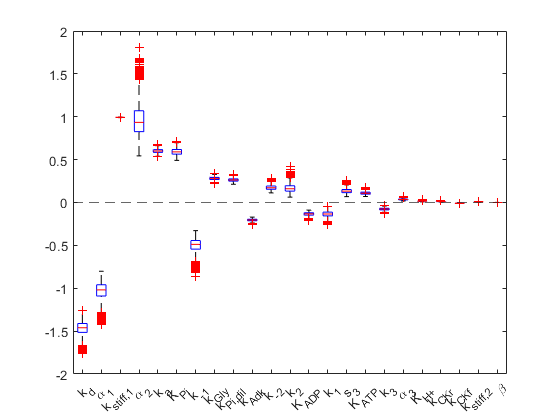

clf;
params_table = readtable('params/params_sens.xlsx');
drop_flag = zeros(24,1);
drop_flag(16) = 1;
params_table = params_table(~drop_flag,:);
params = params_table.Parameter;
sens_force = readtable('../raw_data/Local_sens_Force.xlsx');
sens_force=sens_force(~drop_flag,:);
[~,I]=sort(abs(sens_force.c240),'descend');
s1 = readmatrix('../raw_data/global_sens_cyc_10000_0.1.xlsx');
%writematrix(s1,'global_sens_cyc_10000_0.1.xlsx')
s1=s1(~drop_flag,:);
s1_sort = s1(I,:);
boxplot(s1_sort');hold on;
ylim([-3,3]);
ylim([-2,2]);
yline(0,'--');
ax = gca;
ax.XTick = 1:1:23;
ax.XTickLabels = params(I);
ax.TickLabelInterpreter = "tex";

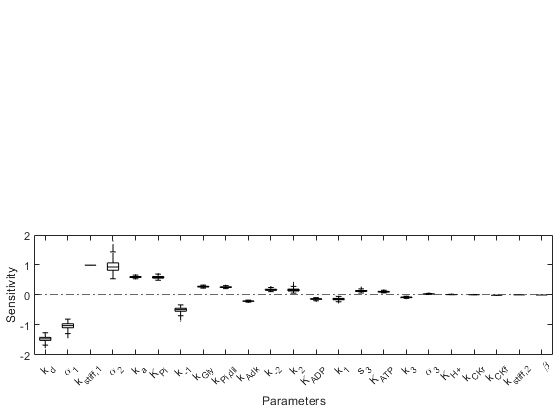

figure(6);clf;
boxplot(s1_sort','Colors','k',"Symbol",".","OutlierSize",0.1);hold on;box on;
ylim([-2,2]);
xlabel('Parameters');
ylabel('Sensitivity');
yline(0,'-.');
ax=gca;
ax.XTickLabels = params(I);
ax.TickLabelInterpreter = "tex";
set(gca,'Unit','Inches')
p = get(gca,'Position');
set(gca,'Unit','Inches','Position',[p(1)-0.4 p(2) 5.4 1.25]);
exportgraphics(figure(6),fullfile(pwd,'figure_7_subplots','figure_7_b.pdf'),'BackgroundColor','w','Resolution',300,'ContentType','vector');